# Radiator Transient Model (EMRAX)

% takes input power, input torque and output rpm and calculates if radiator
% at a certain area is able to sustain the heat rejection required
% (and hence optimize area accordingly)

## Getting data from excel

clear; clc; close all; 
dataTable = readtable('FSPT_endurance.xlsx'); %placeholder name 
t_data = dataTable.Timestamp/1000000; %(s)
torque_data_excel = dataTable.Torque_Right;
torque_data = torque_data_excel*(67.88/32767); %(Nm)
tsv = dataTable.TSV; % Tractive System Current
tsc = dataTable.TSC; % Tractive System Voltage
power_data = tsv .* tsc; %(W)
rpm_data = dataTable.RPM_RR;

## Filter added to ignore zero RPM and shift simulation time to be continuous 

valid_idx = rpm_data ~= 0;
dt_orig = [0; diff(t_data)]; 
t_data = cumsum(dt_orig(valid_idx)); 
torque_data = torque_data(valid_idx);
power_data = power_data(valid_idx);
rpm_data = rpm_data(valid_idx);

## Get efficiency from motor+controller efficiency map 

rpm_pts = [ ...
    2500 4000 5000 5800 5000 4000 3000, ...                   % 96% Contour
    2000 3000 4000 5000 6000 6500 6000 5000 4000 3000, ...    % 95% Contour
    1500 2000 3000 4000 5000 6000 7000 7900 7000 6000 5000 4000 3000 2000, ... % 94% Contour
    1000 1500 2000 3000 4000 5000 6000 7000 8000 8000 7000 6000 5000 4000 3000 2000, ... % 90% Contour
    500  1000 1500 2000 3000 4000 5000 6000 7000 8000 8000 7000 6000 5000 4000 3000 2000 1000]; % 86% Contour

torque_pts = [ ...
    50 57 54 46 33 30 33, ...                                 % 96% Contour
    52 66 69 67 61 48 32 26 25 28, ...                        % 95% Contour
    45 68 78 80 80 80 79 60 33 25 23 22 24 30, ...            % 94% Contour
    45 72 86 90 90 90 90 88 86 48 23 18 16 16 18 22, ...      % 90% Contour
    30 65 88 97 97 97 97 96 94 90 42 17 9  7  7  7  8  12];   % 86% Contour

eff_pts = [ ...
    96 96 96 96 96 96 96, ...
    95 95 95 95 95 95 95 95 95 95, ...
    94 94 94 94 94 94 94 94 94 94 94 94 94 94, ...
    90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90, ...
    86 86 86 86 86 86 86 86 86 86 86 86 86 86 86 86 86 86] / 100;

F = scatteredInterpolant(rpm_pts(:), torque_pts(:), eff_pts(:), 'linear', 'nearest');

##     Setting up initial parameters

    % MAKE CHANGES HERE
    A_face_fixed = 0.0286;
    fpi_fixed = 18;
    H_fixed = 0.35; %(m)
    d = 0.032; %(m), depth of radiator
    W = A_face_fixed/H_fixed; %(m), width of radiator 
    mdot_coolant = 10; %(L/min), per side, fixed before the loop
    T_air_in = 25; %(degC)
    T_coolant_initial = 25; %(degC)
    r_wheel = 0.11; %(m)
    gear_ratio = 4.5;
    ram_air_factor = 0.7; %placeholder value 

##     Fixed Properties

    import py.CoolProp.CoolProp.*

    a_tube = 0.002; b_tube = d; tube_pitch = 0.010;
    D_h_tube = (4*a_tube*b_tube)/(2*(a_tube+b_tube));
    A_tube = a_tube*b_tube;
    f_height = 0.008; f_thickness = 0.00008;
    k_fin = 237;

    T_air_K = 298.15; P_air = 101325;
    rho_air = PropsSI('D','T',T_air_K,'P',P_air,'Air');
    mu_air  = PropsSI('V','T',T_air_K,'P',P_air,'Air');
    k_air   = PropsSI('L','T',T_air_K,'P',P_air,'Air');
    cp_air  = PropsSI('C','T',T_air_K,'P',P_air,'Air');
    Pr_air  = PropsSI('Prandtl','T',T_air_K,'P',P_air,'Air');

    P_water = 101325; % 1 atm
    rho_water = PropsSI('D','T',323.15,'P',P_water,'Water');
    cp_water  = PropsSI('C','T',323.15,'P',P_water,'Water');

    mdot_coolant_kgs = (mdot_coolant*rho_water)/60000; % L/min -> kg/s, fixed for the whole run

    props = struct('T_air_in',T_air_in,'rho_air',rho_air,'mu_air',mu_air,'k_air',k_air, ...
        'cp_air',cp_air,'Pr_air',Pr_air,'rho_water',rho_water,'cp_water',cp_water, ...
        'd',d,'a_tube',a_tube,'A_tube',A_tube,'D_h_tube',D_h_tube,...
        'tube_pitch',tube_pitch,'f_height',f_height,...
        'f_thickness',f_thickness,'k_fin',k_fin);

## Epsilon NTU function

    function [Q_rejected,water_state] = Q_epsilonNTU(T_coolant_in, v_air, mdot_coolant_kgs, A_face, fpi, H, props, water_state)
    import py.CoolProp.CoolProp.*
    % --- water properties as func of temp ---
    if isempty(water_state) || abs(T_coolant_in - water_state.T_last) >= 1 %change here for temp step
        P_water = 101325;
        water_state.T_last = T_coolant_in;
        water_state.k_water = PropsSI('L','T',T_coolant_in+273.15,'P',P_water,'Water');
        water_state.mu_water = PropsSI('V','T',T_coolant_in+273.15,'P',P_water,'Water');
        water_state.Pr_water = PropsSI('Prandtl','T',T_coolant_in+273.15,'P',P_water,'Water');
    end
    k_water  = water_state.k_water;
    mu_water = water_state.mu_water;
    Pr_water = water_state.Pr_water;

    % --- water side h ---
    n_tubes = floor(H/props.tube_pitch);
    mdot_tube = mdot_coolant_kgs/n_tubes;
    v_water = mdot_tube/(props.rho_water*props.A_tube);
    Re_water = (props.rho_water*v_water*props.D_h_tube)/mu_water;
    if Re_water < 2300
        Nu_water = 3.66;
    else
        Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3); 
    end
    h_water = (Nu_water*k_water)/props.D_h_tube;

    % --- air side h ---
    sigma_c = 1 - ((fpi*props.f_height*props.f_thickness)/0.0254+props.a_tube)/(props.a_tube+props.f_height);
    G_air = props.rho_air*v_air/sigma_c;
    f_spacing = 0.0254/fpi;
    D_h_fin = (4*f_spacing*props.f_height)/(2*(f_spacing+props.f_height));
    Re_air = G_air*D_h_fin/props.mu_air;
    J_air = 0.174/(Re_air^0.383);
    h_air = J_air*G_air*props.cp_air/(props.Pr_air^0.667);

    U = 1/((1/h_air)+(1/h_water));

    % --- capacity rates ---
    C_air = props.rho_air*v_air*props.cp_air*A_face;
    C_water = mdot_coolant_kgs*props.cp_water;
    C_min = min(C_air, C_water);
    C_max = max(C_air, C_water);
    C_star = C_min / C_max;

    % --- fin efficiency & total surface area ---
    W = A_face/H;
    A_primary = 2*props.d*W*n_tubes;
    A_secondary = 2*props.f_height*props.d*fpi*W*n_tubes/0.0254;
    m_fin = sqrt(2*h_air/(props.k_fin*props.f_thickness));
    L_c = props.f_height/2 + props.f_thickness/2;
    eta_f = tanh(m_fin*L_c)/(m_fin*L_c);
    eta_0 = 1 - (A_secondary/(A_primary+A_secondary))*(1-eta_f);
    A_fins = eta_0*(A_primary+A_secondary);

    % --- epsilon-NTU ---
    NTU = (U*A_fins)/C_min;
    epsilon = 1 - exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1));

    Q_rejected = epsilon*C_min*(T_coolant_in - props.T_air_in);
    end

##    Simulation from test run data 

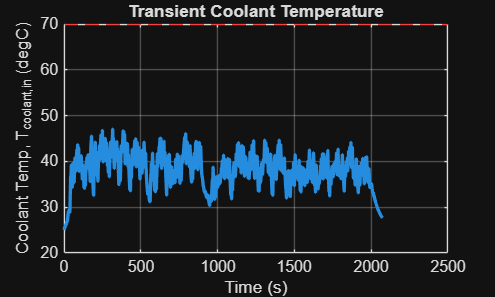

n_tubes = floor(H_fixed/tube_pitch);
m_water = props.rho_water*props.A_tube*W*n_tubes; %mass of water in radiator at a time 

T_old = T_coolant_initial; %initial condition
             
N = length(t_data);
T_history = zeros(N,1);
Q_gen_history = zeros(N,1);
Q_rej_history = zeros(N,1);
v_air_history = zeros(N,1);
water_state = [];

T_history(1) = T_old;

for k = 1:N-1
    dt = t_data(k+1) - t_data(k); 

    % --- vehicle & air speed ---
    omega_motor = rpm_data(k)*2*pi/60; %(rad/s)
    omega_wheel = omega_motor/gear_ratio;
    v_car = r_wheel*omega_wheel; %(m/s)
    v_air = ram_air_factor*v_car; %(m/s)
    v_air = max(v_air, 0.5); % floor to avoid v_air = 0 (stalled/idle) blowing up h_air
    v_air_history(k) = v_air;

    % --- heat generated ---
    eff = F(rpm_data(k), torque_data(k));
    P_check = torque_data(k)*rpm_data(k)*2*pi/60; % (W)
    if torque_data(k) > 92 || power_data(k) > 80000
       warning('t=%.2fs: T=%.1f Nm, RPM=%.0f, logged P=%.0f W, computed P=%.0f W', ...
            t_data(k), torque_data(k), rpm_data(k), power_data(k), P_check);
    end
    eff = min(max(eff, 0), 1); % efficiency between 0-1 (decimal)
    Q_gen = power_data(k)*(1-eff); %both motor and motor controller
    Q_gen_history(k) = Q_gen;

    % --- heat rejected ---
    Q_rejected = Q_epsilonNTU(T_old, v_air, mdot_coolant_kgs, A_face_fixed, fpi_fixed, H_fixed, props, water_state);
    Q_rej_history(k) = Q_rejected;

    % --- lumped capacitance update ---
    T_new = T_old + dt*(Q_gen - Q_rejected)/(m_water*cp_water);
    T_history(k+1) = T_new;
    T_old = T_new;
end

Q_gen_history(end) = Q_gen_history(end-1);
Q_rej_history(end) = Q_rej_history(end-1);
v_air_history(end) = v_air_history(end-1);

figure;
plot(t_data, T_history, 'LineWidth', 2); hold on;
yline(70, 'r--', '70degC limit');
xlabel('Time (s)'); ylabel('Coolant Temp, T_{coolant,in} (degC)');
title('Transient Coolant Temperature');
grid on;


[T_peak, peak_idx] = max(T_history);
t_peak = t_data(peak_idx);
violation = T_history > 70;
if any(violation)
    t_start = t_data(find(violation,1,'first'));
    fprintf('VIOLATION: peak %.1f degC at t=%.1fs, first exceeded 70 at t=%.1fs\n', T_peak, t_peak, t_start);
else
    fprintf('OK: peak %.1f degC, stayed under limit.\n', T_peak);
end

OK: peak 47.1 degC, stayed under limit.


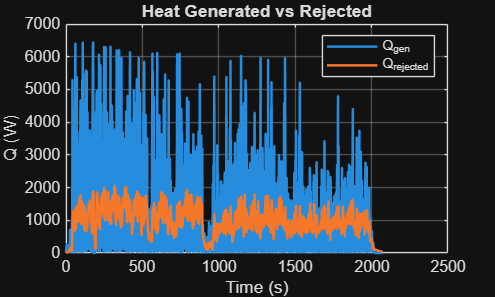


figure;
plot(t_data, Q_gen_history, 'LineWidth', 1.5); hold on;
plot(t_data, Q_rej_history, 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Q (W)');
legend('Q_{gen}', 'Q_{rejected}');
title('Heat Generated vs Rejected');
grid on;

t_threshold = 100;
valid_idx = find(t_data > t_threshold);
[T_min, min_idx_subset] = min(T_history(valid_idx));
t_min = t_data(valid_idx(min_idx_subset));
fprintf('Minimum Temp (after %.0fs): %.1f degC at t=%.1fs\n', t_threshold, T_min, t_min);

Minimum Temp (after 100s): 27.7 degC at t=2072.8s
